# Kalman Filter

[YouTube(32:00)](https://www.youtube.com/watch?v=qCZ2UTgLM_g&t=24s)

clear all
addpath(genpath('D:\OneDrive\MATLAB_FILES\UsefulFunctions'));

## Example - Voltage

The goal is approximate voltage of 14.4[v] given random normally distributed noise of 4[v]

z - measurment = voltage (m = 1)

x - state is also voltage (n = 1)


$$x_{k+1} = [1]\cdot x_k \\
z_k = [1] \cdot x_k + v_k  \\
\text{Resulting Mtrices are:} \\
A = 1;
H  = 1;
Q \approx 0; 
R = 4 \text{ (for initialization)}; \\
\text{Initialization "guess":} \\
\hat x_0^- = 14, P_0^- = 6$$


getVolt = @() 14.4 + 4.0*randn;

dt = 0.2;
t = 0:dt:10;
Nsamples = length(t);

Xsaved = zeros(Nsamples,1);
Zsaved = zeros(Nsamples,1);
KGSaved = zeros(Nsamples,1);
Psaved = zeros(Nsamples,1);

for k = 1:Nsamples

    z = getVolt();
    [volt, voltP, KG] = SimpleKalman(z);

    Xsaved(k) = volt;
    Zsaved(k) = z;
    KGSaved(k) = KG;
    Psaved(k) = voltP;
end

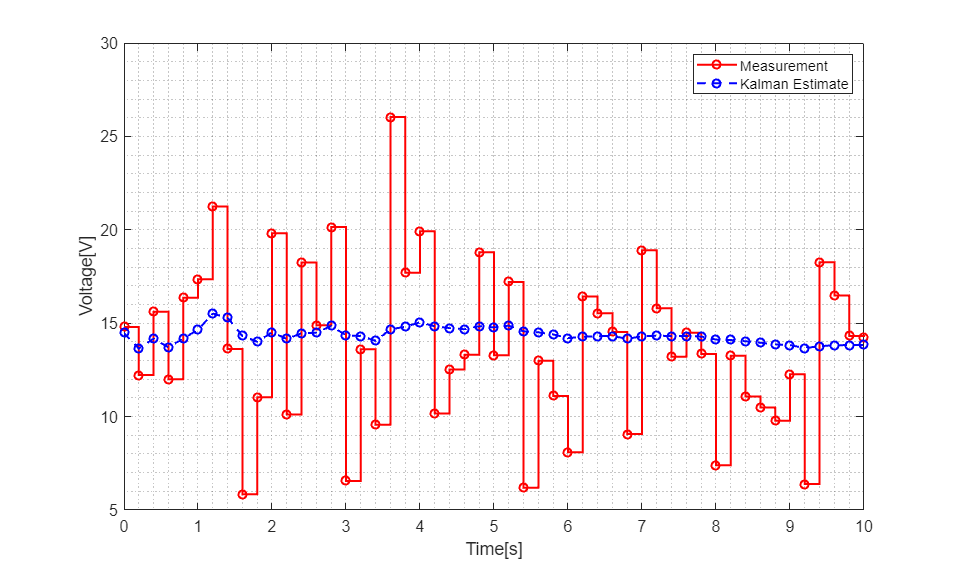

figure('Position',[0 0 1000 600])
stairs(t, Zsaved, 'ro-', 'LineWidth',1.5,'DisplayName','Measurement'); hold on;
plot(t, Xsaved, 'bo--','LineWidth',1.5,'DisplayName','Kalman Estimate');
xlabel('Time[s]')
ylabel('Voltage[V]')
legend
grid minor
set(gca, 'Fontsize', 12)

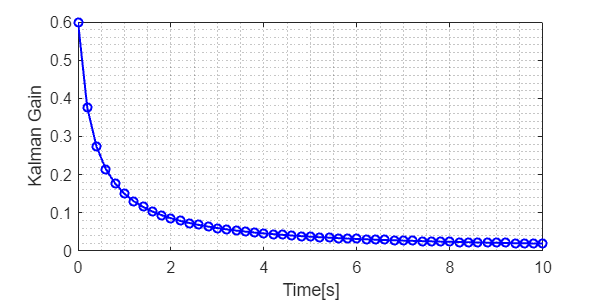

figure('Position',[0 0 600 300])
plot(t, KGSaved, 'bo-', 'LineWidth',1.5,'DisplayName','Kalman Gain');
xlabel('Time[s]')
ylabel('Kalman Gain')
grid minor
set(gca, 'Fontsize', 12)

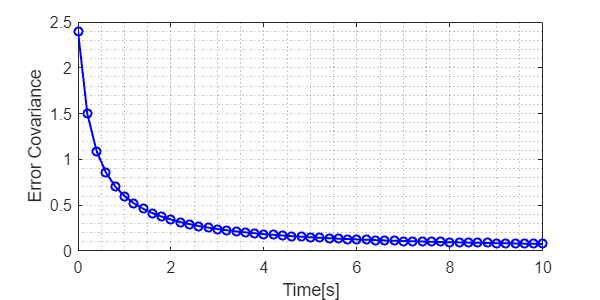

figure('Position',[0 0 600 300])
plot(t, Psaved, 'bo-', 'LineWidth',1.5,'DisplayName','Error Covariance');
xlabel('Time[s]')
ylabel('Error Covariance')
grid minor
set(gca, 'Fontsize', 12)